# Fugtig luft

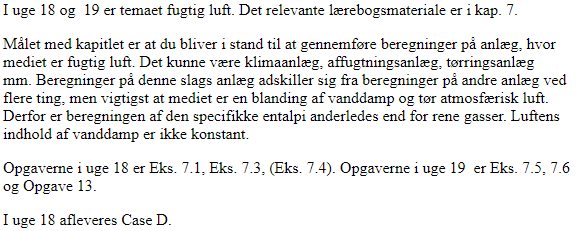

clc; clear;
CP = py.importlib.import_module("CoolProp.CoolProp");

ans = -1

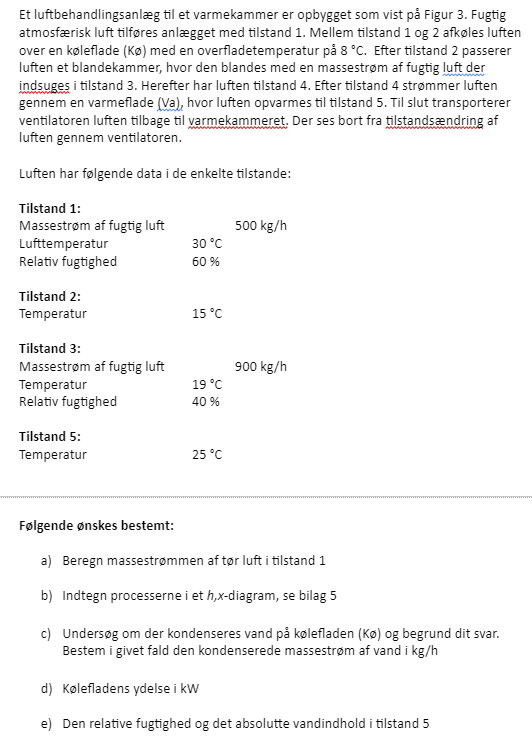

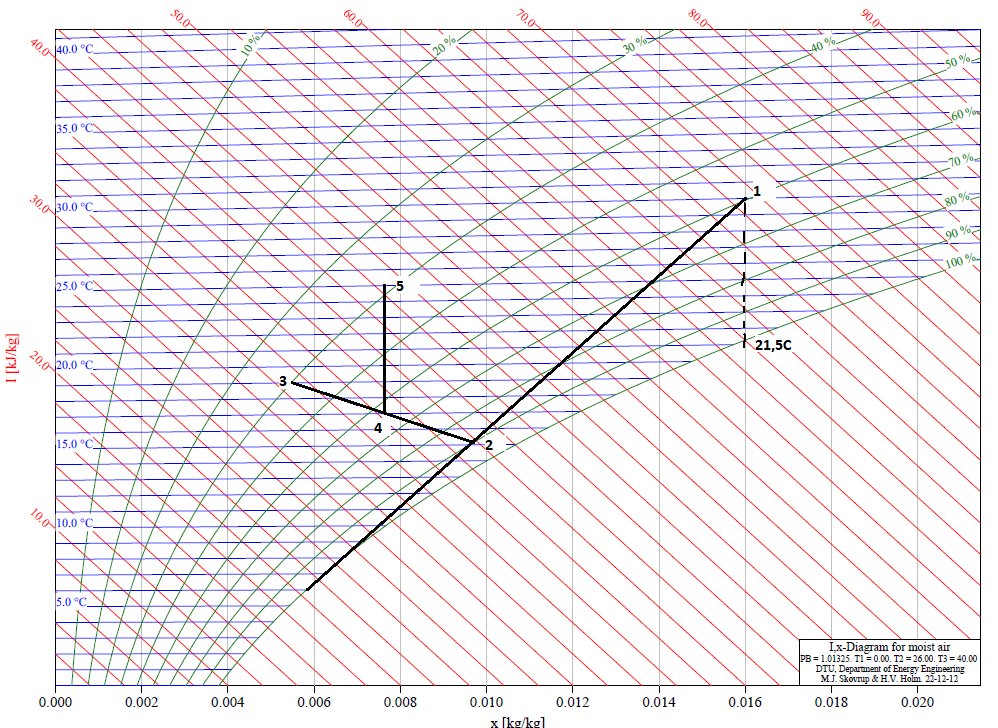

% Opgave a)

qmf = 500; % massestrøm af luft kg/hr
x = 0.016; % absolutte vandindhold

qmL = qmf * 1/(1+x) % kg/hr

qmL = 492.1260


% Opgave b - se billede

Betingelsen for udfældning af vand på kølefladen (Kø), er, at overfadetemperaturen her er mindre end dugtemperaturen, som aflæses lodret under punkt 1 og bestemmes til 21,5C. Da overfadetemperaturen på Kø er 8C, er betingelsen tilfredsstillet. En massebalance giver:


$$q_{mv} = q_{mL}(x_2 - x_1)$$


x1 = 0.016

x1 = 0.0160

x2 = 0.01 % fra opgaven, jeg ville nok vælge 0.009

x2 = 0.0100

qmv = qmL * (x1 - x2)

qmv = 2.9528

Der aflæses på diagrammet


$$\Phi_k = q_{mL}(h1 - h2)$$


h1 = 71.6;
h2 = 39.6;
hr = 3600; % alle andre er opgivet i timer, jeg omdanner til sekunder

phi_K = qmL*(h1 - h2)/hr % svaret er i kW eftersom entalpierne er i kJ/kg

phi_K = 4.3745

Værdierne aflæses i h-x digrammet

x = 0.007 kg/kg

phi = 37%

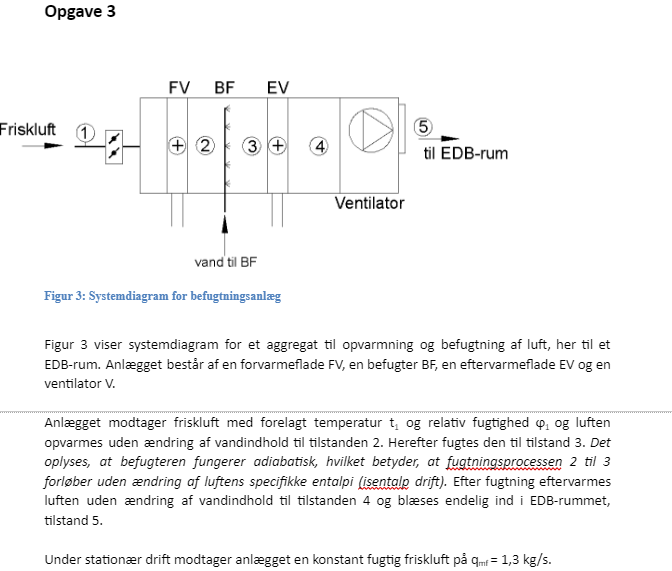

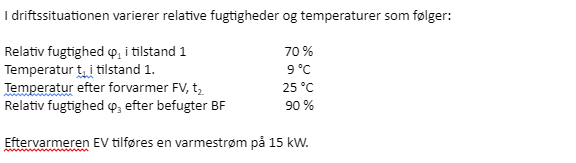

hr = 3600;

x = 0.0053;
qmf = 1.3*hr

qmf = 4680


qmL = qmf * 1/(1+x)

qmL = 4.6553e+03


$$q_{mL} = q_{mf} \cdot \frac{1}{1+x} = 4.655 \cdot 10^3 \,\mathrm\frac{kg}{hr}$$


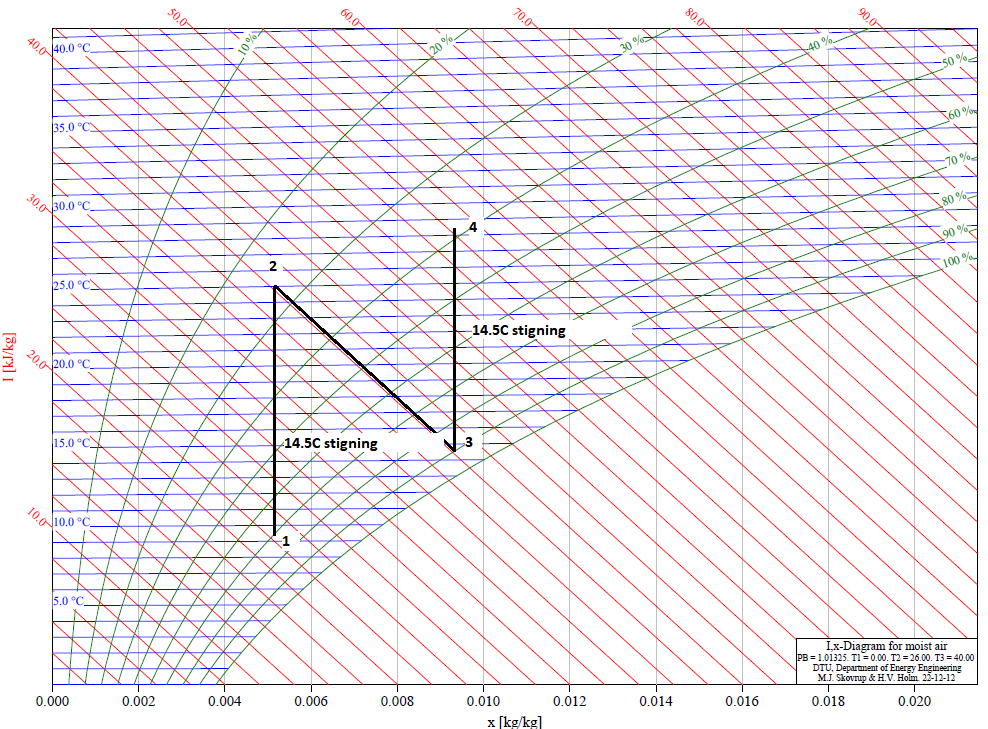

kun 14C stigning

pkt1 = [9, 21.7, 0.0053, 70];
pkt2 = [25, 38.3, 0.0053, 27.5];
pkt3 = [9, 38.3, 0.0093, 90];

% til tabel
pkts = ["Punkt 1","Punkt 2", "Punkt 3"];
names = ["Punkter","T | x | h | psi (%)"];

disp(table(pkts',[pkt1;pkt2;pkt3], VariableNames=names))

     Punkter           T | x | h | psi (%)       
    _________    ________________________________

    "Punkt 1"     9      21.7    0.0053        70
    "Punkt 2"    25      38.3    0.0053      27.5
    "Punkt 3"     9      38.3    0.0093        90




$$\Phi_{FV} = q_{mL}(h1 - h2)$$


h1 = 21.7;
h2 = 38.3;
phi_FV = qmL*(h2 - h1)/hr

phi_FV = 21.4662


$$q_{mv} = q_{mL}(x_3 - x_2)$$



x2 = 0.0053

x2 = 0.0053

x3 = 0.0093 % fra opgaven, jeg ville nok vælge 0.009

x3 = 0.0093

qmv = qmL * (x3 - x2)

qmv = 18.6213

Bare aflæs på grafen